'(ch2p1)'               % Display label.

ans = '(ch2p1)'

'How are you?'          % Display string.

ans = 'How are you?'

-3.96                   % Display scalar number -3.96.

ans = -3.9600

-4 + 7i                 % Display complex number -4 + 7i.

ans = -4.0000 + 7.0000i

-5 - 6j                 % Display complex number -5 - 6j.

ans = -5.0000 - 6.0000i


(-4 + 7i) + (-5 - 6i)   % Add two complex numbers and display sum.

ans = -9.0000 + 1.0000i

(-4 + 7j) * (-5 - 6j)   % Multiply two complex numbers and display product.

ans = 62.0000 -11.0000i


M = 5                   % Assign 5 to M and display.

M = 5

N = 6                   % Assign 6 to N and display.

N = 6

P = M + N               % Assign M + N to P and display.

P = 11


Q = 3 + 4j              % Define complex number Q.

Q = 3.0000 + 4.0000i

MagQ = abs(Q)           % Find magnitude of Q.

MagQ = 5

ThetaQ = (180/pi) * angle(Q) % Find the angle of Q in degrees.

ThetaQ = 53.1301

'(ch2p2)'               % Display label.

ans = '(ch2p2)'

P1 = [1 7 -3 23]        % Store polynomial s^3 + 7s^2 - 3s + 23 as P1 and display.

P1 =      1     7    -3    23


'(ch2p7)'               % Display label.

ans = '(ch2p7)'


numf = [7 9 12]         % Define numerator of F(s).

numf =      7     9    12



denf = conv(poly([0 -7]), [1 10 100]); % Define denominator of F(s).

[K, p, k] = residue(numf, denf) % Find residues and assign to K;

K =    0.2554 - 0.3382i
   0.2554 + 0.3382i
  -0.5280 + 0.0000i
   0.0171 + 0.0000i


p =   -5.0000 + 8.6603i
  -5.0000 - 8.6603i
  -7.0000 + 0.0000i
   0.0000 + 0.0000i



k =

     []



                                 % find roots of denominator and assign to p;
                                 % find constant and assign to k.

'(ch2p8) Example 2.3'   % Display label.

ans = '(ch2p8) Example 2.3'


numy = 32;              % Define numerator.
deny = poly([0 -4 -8]); % Define denominator.

[r, p, k] = residue(numy, deny) % Calculate residues, poles, and direct quotient.

r =      1
    -2
     1


p =     -8
    -4
     0



k =

     []



'(ch2p9)'                           % Display label.

ans = '(ch2p9)'

'Vector Method, Polynomial Form'    % Display label.

ans = 'Vector Method, Polynomial Form'


numf = 150 * [1 2 7];               % Store 150(s^2 + 2s + 7) in numf and display.
denf = [1 5 4 0];                   % Store s(s + 1)(s + 4) in denf and display.

'F(s)'                              % Display label.

ans = 'F(s)'

F = tf(numf, denf)                  % Form F(s) and display.


F =
 
  150 s^2 + 300 s + 1050
  ----------------------
    s^3 + 5 s^2 + 4 s
 
Continuous-time transfer function.
Model Properties



clear                               % Clear previous variables from workspace.

'Vector Method, Factored Form'       % Display label.

ans = 'Vector Method, Factored Form'


numg = [-2 -4];                     % Store (s + 2)(s + 4) in numg and display.
deng = [-7 -8 -9];                  % Store (s + 7)(s + 8)(s + 9) in deng and display.
K = 20;                              % Define K.

'G(s)'                              % Display label.

ans = 'G(s)'

G = zpk(numg, deng, K)              % Form G(s) and display.


G =
 
   20 (s+2) (s+4)
  -----------------
  (s+7) (s+8) (s+9)
 
Continuous-time zero/pole/gain model.
Model Properties



clear                               % Clear previous variables from workspace.

'Rational Expression Method, Polynomial Form' % Display label.

ans = 'Rational Expression Method, Polynomial Form'


s = tf('s');                        % Define 's' as an LTI object in polynomial form.
F = 150 * (s^2 + 2*s + 7) / (s * (s^2 + 5*s + 4))


F =
 
  150 s^2 + 300 s + 1050
  ----------------------
    s^3 + 5 s^2 + 4 s
 
Continuous-time transfer function.
Model Properties


                                    % Form F(s) as an LTI transfer function in polynomial form.
G = 20 * (s + 2) * (s + 4) / ((s + 7) * (s + 8) * (s + 9))


G =
 
     20 s^2 + 120 s + 160
  --------------------------
  s^3 + 24 s^2 + 191 s + 504
 
Continuous-time transfer function.
Model Properties


                                    % Form G(s) as an LTI transfer function in polynomial form.

clear                               % Clear previous variables from workspace.

'Rational Expression Method, Factored Form'  % Display label.

ans = 'Rational Expression Method, Factored Form'


s = zpk('s');                       % Define 's' as an LTI object in factored form.
F = 150 * (s^2 + 2*s + 7) / (s * (s^2 + 5*s + 4))


F =
 
  150 (s^2 + 2s + 7)
  ------------------
    s (s+1) (s+4)
 
Continuous-time zero/pole/gain model.
Model Properties


                                    % Form F(s) as an LTI transfer function in factored form.
G = 20 * (s + 2) * (s + 4) / ((s + 7) * (s + 8) * (s + 9))


G =
 
   20 (s+2) (s+4)
  -----------------
  (s+7) (s+8) (s+9)
 
Continuous-time zero/pole/gain model.
Model Properties


                                    % Form G(s) as an LTI transfer function in factored form.

'(ch2p10)'                     % Display label.

ans = '(ch2p10)'


'Coefficients for F(s)'        % Display label.

ans = 'Coefficients for F(s)'

numftf = [10 40 60];           % Form numerator of F(s) = (10s^2 + 40s + 60) / (s^3 + 4s^2 + 5s + 7).
denftf = [1 4 5 7];            % Form denominator of F(s).

'Roots for F(s)'               % Display label.

ans = 'Roots for F(s)'

[numfzp, denfzp] = tf2zp(numftf, denftf) 

numfzp =   -2.0000 + 1.4142i
  -2.0000 - 1.4142i


denfzp =   -3.1163 + 0.0000i
  -0.4418 + 1.4321i
  -0.4418 - 1.4321i


                               % Convert F(s) to factored form.

'Roots for G(s)'               % Display label.

ans = 'Roots for G(s)'

numgzp = [-2 -4];             % Form numerator of G(s) = 10(s + 2)(s + 4).
K = 10;                        % Define K.
dengzp = [0 -3 -5];            % Form denominator of G(s) = 10(s + 2)(s + 4) / [s(s + 3)(s + 5)].

'Coefficients for G(s)'        % Display label.

ans = 'Coefficients for G(s)'

[numgtf, dengtf] = zp2tf(numgzp', dengzp', K) 

numgtf =      0    10    60    80


dengtf =      1     8    15     0


                               % Convert G(s) to polynomial form.

'(ch2p11)'                     % Display label.

ans = '(ch2p11)'


'Fzpk1(s)'                     % Display label.

ans = 'Fzpk1(s)'

Fzpk1 = zpk([-2 -4], [0 -3 -5], 10);  
                                % Form Fzpk1(s) = 10(s + 2)(s + 4) / [s(s + 3)(s + 5)].

'Ftf1'                         % Display label.

ans = 'Ftf1'

Ftf1 = tf(Fzpk1);              % Convert Fzpk1(s) to coefficient form.

'Ftf2'                         % Display label.

ans = 'Ftf2'

Ftf2 = tf([10 40 60], [1 4 5 7]);  
                                % Form Ftf2(s) = (10s^2 + 40s + 60) / (s^3 + 4s^2 + 5s + 7).

'Fzpk2'                        % Display label.

ans = 'Fzpk2'

Fzpk2 = zpk(Ftf2);             % Convert Ftf2(s) to factored form.

'(ch2p12)'                 % Display label.

ans = '(ch2p12)'

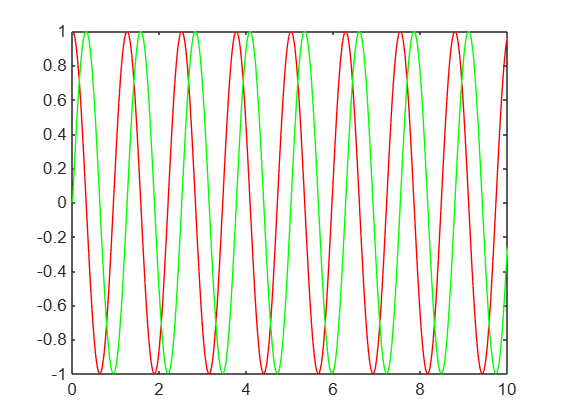


t = 0:0.01:10;             % Specify time range and increment.
f1 = cos(5 * t);           % Define f1 as cos(5t).
f2 = sin(5 * t);           % Define f2 as sin(5t).

plot(t, f1, 'r', t, f2, 'g');  % Plot f1 in red and f2 in green.